%% lidar_plot_offline.m  ---------------------------------------------
% 저장한 한 프레임(csv) 불러와서 폴라 스캔 재현

% ---------- 1. 파일 읽기 ----------
fileName = 'resource/data/lidar/lidar_000033.csv';   % ← 경로/이름 수정
rangeMat = readmatrix(fileName);

% ---------- 2. 센서 파라미터 (Webots 설정과 동일해야 함) ----------
hRes = size(rangeMat,2);          % 수평 해상도
nLayer = size(rangeMat,1);        % 수직 레이어 수
fov   = deg2rad(60);              % 수평 FoV [rad]  ← 예: 60°
maxR  = 8.0;                      % 최대 거리 [m]   ← world 파일과 일치
circleR=3.0;

% ---------- 3. 가운데 레이어 하나 선택 ----------
rValues  = rangeMat( ceil(nLayer/2), : );

% ---------- 4. 극 → 직교 변환 ----------
thetaVec = linspace( fov/2 , -fov/2 , hRes );  % +왼 → −오른
xEnd = -rValues .* sin(thetaVec);
yEnd =  rValues .* cos(thetaVec);

% ---------- 5. 유효 히트 필터 (빈 빔 제거) ----------
tol   = 6;%0.05;                               % 5 cm 여유
isHit = (rValues < maxR - tol) & ~isinf(rValues) & ~isnan(rValues);

% ---------- 6. 그림 ----------
figure('Name','Offline LiDAR Polar Scan','NumberTitle','off');
ax = axes; hold(ax,'on'); axis(ax,'equal'); grid(ax,'on');
xlabel('X [m]'); ylabel('Y [m]'); title('LiDAR Polar Scan (offline)');

% (a) 모든 빔 파란 선
for k = 1:hRes
    line(ax,[0 xEnd(k)],[0 yEnd(k)],'Color',[0 0.6 1 0.5]);  % 0.5=알파
end

% (b) 히트 점 빨간 scatter
scatter(ax,xEnd(isHit),yEnd(isHit),25,'filled','r');


%% -------- 7. DBSCAN 군집화 · 객체별 거리 계산 -----------------
% ▶ 7-1) (x,y) 히트 좌표 배열
xyHits = [xEnd(isHit).' , yEnd(isHit).'];      % [N×2]

% ▶ 7-2) DBSCAN 실행  (eps·minPts는 장면 규모에 따라 조정)
eps    = 0.15;    % 한 클러스터 내 최대 점-간 거리 [m]
minPts = 4;       % 최소 점 개수(노이즈 제거용)
clabel = dbscan(xyHits, eps, minPts);          % 벡터 길이 = N

% ▶ 7-3) 노이즈(라벨 −1) 제거
valid  = clabel > 0;
xyC    = xyHits(valid,:);    cID = clabel(valid);

% ▶ 7-4) 클러스터별 특성치
uID  = unique(cID);                  % 실제 객체ID 목록
nObj = numel(uID);                   % 검출된 물체 개수
objCentroid = zeros(nObj,2);         % (x,y) 중심
objDist     = zeros(nObj,1);         % 원점(로봇)까지 거리

for i = 1:nObj
    idx = (cID == uID(i));
    objCentroid(i,:) = mean(xyC(idx,:),1);         % 산술평균
    objDist(i)       = hypot(objCentroid(i,1), ...
                             objCentroid(i,2));    % √(x²+y²)
end

% ▶ 7-5) 시각화 : 각 클러스터 다른 색 + 중심 '×'
cmap = lines(max(uID));     % 색상 팔레트
for i = 1:nObj
    idx = (cID == uID(i));
    scatter(ax, xyC(idx,1), xyC(idx,2), 30, ...
            'filled', 'MarkerFaceColor', cmap(uID(i),:));
    plot(ax, objCentroid(i,1), objCentroid(i,2), ...
         'kx', 'MarkerSize',10,'LineWidth',2);
    text(objCentroid(i,1), objCentroid(i,2), ...
        sprintf('  %.2fm',objDist(i)) , ...
        'Color',cmap(uID(i),:),'FontWeight','bold', 'FontSize',20);
end
title(ax, sprintf('LiDAR Scan – %d objects', nObj));

fprintf('Detected %d objects\n', nObj);

Detected 2 objects


disp(table((1:nObj).', objCentroid, objDist, ...
     'VariableNames',{'ID','Centroid_xy','Range_m'}));

    ID        Centroid_xy         Range_m
    __    ____________________    _______

    1     -0.25918      1.5174     1.5393
    2       0.2134     0.77661    0.80539



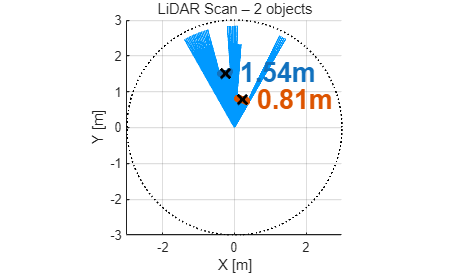


t = linspace(0,2*pi,360);
% plot(ax,maxR*cos(t),maxR*sin(t),'k:');
% xlim(ax,[-maxR maxR]); ylim(ax,[-maxR maxR]);
plot(ax,circleR*cos(t),circleR*sin(t),'k:');
xlim(ax,[-circleR circleR]); ylim(ax,[-circleR circleR]);

% 1) 원하는 좌표 지정 (행, 열)
% obs = [8 13;
%        14 7;];

nc=20

nc = 20

nl=26

nl = 26

obs_tmp=objCentroid.*10

obs_tmp =    -2.5918   15.1737
    2.1340    7.7661


obs_tmp(:,2)=obs_tmp(:,2)

obs_tmp =    -2.5918   15.1737
    2.1340    7.7661


obs_tmp(:,1)=obs_tmp(:,1)+10;%nc/2
obs=ceil(obs_tmp)

obs =      8    16
    13     8


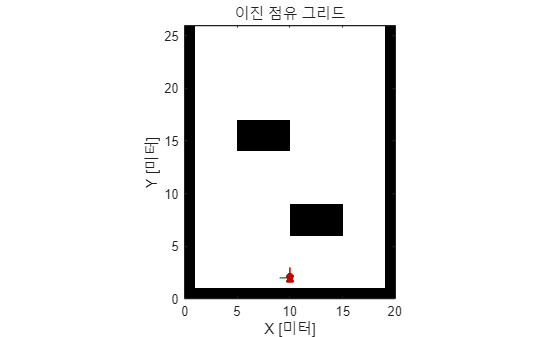


obsRow = nl - obs(:,2) + 1;   % y  → row (위·아래 뒤집기)
obsCol = obs(:,1);            % x  → col
obsRC  = [obsRow obsCol];     % [row col]  형태

binMap   = createBinaryMap(nl,nc,obsRC,[3,4]);


% fig = figure("Name","simpleMap");
% set(fig, "Visible","on");
% ax = axes(fig);
% 
% show(binaryOccupancyMap(binMap),"Parent",ax);

mapMatrix = binMap;
mapScale = 1;

scanAngles = -3*pi/8:pi/8:3*pi/8;
maxRange = 12;
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

% Max speed parameters
maxLinSpeed = 0.3;
maxAngSpeed = 0.3;

% Initial pose of the robot
initX = 10;
initY = 2;
initTheta = pi/2;

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off
set(gcf, 'Color', 'w');

## Simulate

% save("trainedObstacleAvoidanceAgent_250618.mat", "obstacleAvoidanceAgent");
% load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
% set_param("exampleHelperAvoidObstaclesMobileRobot","StopTime","200");
% out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");

% 1. 에이전트 로드
load("trainedObstacleAvoidanceAgent1.mat", "obstacleAvoidanceAgent");
% load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
% 2. 모델 열기
% mdl = "exampleHelperAvoidObstaclesMobileRobot";
mdl = 'AOMR_reward_goal';
obAgent = obstacleAvoidanceAgent;  
load_system(mdl);                                       % 창 안 띄움
set_param([mdl '/Agent'],'Agent','obstacleAvoidanceAgent');
sampleTime = 0.1;                                       % ← 고정 샘플타임



% 3. Simulink 모델에 에이전트 연결
%    "Agent"라는 이름의 block이 Simulink 안에 있어야 함
%    이 block은 RL Agent 블록이어야 하며,
%    파라미터 "Agent"에 obstacleAvoidanceAgent를 연결
% rlAgentBlock = mdl + "/Agent";
% set_param(rlAgentBlock, "Agent", "obstacleAvoidanceAgent");

% 4. 시뮬레이션 시간 설정
set_param(mdl, "StopTime", "200");

% 5. 시뮬레이션 실행
out = sim(mdl);

## Visualize

To visualize the simulation of the robot driving around the environment with range sensor readings, use the helper, `exampleHelperAvoidObstaclesPosePlot`.

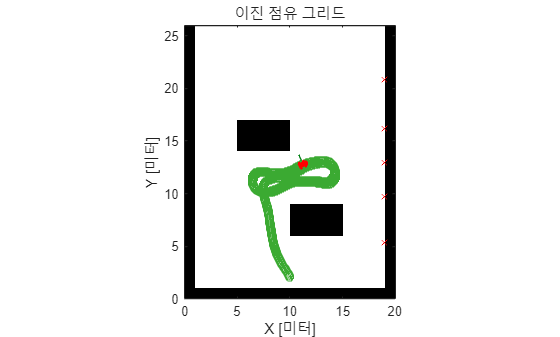

for i = 1:5:size(out.range,3)
    u = out.pose(i,:);
    r = out.range(:,:,i);
    
    AvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
    % hold on;
    scatter(ax,out.pose(1:i,1), out.pose(1:i,2))
    drawnow;
end



% figure();
% plot(out.pose(:,1), out.pose(:,2))

robot_init_x=10;
robot_init_y=2;
robot_current_x=10;
robot_current_y=2;

%% 0) 로봇 스프라이트 한 번만 준비
imgFile  = "resource/img/robot/nao_up_img.png";
imgNAO   = imread(imgFile);            % RGBA PNG(투명 배경)
spriteW  = 4;                        % 지도 좌표계에서 가로 0.5 m 로 보이도록
spriteH  = spriteW * size(imgNAO,1)/size(imgNAO,2);   % 종횡비 유지

% 최초 위치(전후 루프 앞쪽에 이미 있던 robot_pos 사용)
hNAO = image(ax,...
    "CData",      imgNAO, ...
    "XData",      robot_pos(1) + [-spriteW/2,  spriteW/2], ...
    "YData",      robot_pos(2) + [ spriteH/2, -spriteH/2], ... % 이미지 y 축 뒤집기
    "AlphaData",  imgNAO(:,:,end));      % PNG 투명 채널 사용
uistack(hNAO,"top")     

%% ---- 8. 휴머노이드 추종 시뮬레이션 -------------------------------
% 전·측 이동 파라미터
stepFwd = 1;      % 전진 1 m
stepLat = 0.7;    % 좌우 0.7 m

% 로봇 초기 위치
robot_pos = [robot_init_x, robot_init_y];  % [x  y]

% 시각화 준비
hold(ax,'on');
hPath = animatedline(ax,'Color','r','Marker','.','LineStyle','none');

% 최대 반복(또는 원하는 종료 조건)
nIter = 25;
for k = 1:nIter
    % 1) 목표 y
    targetY = robot_pos(2) + 2;

    % 2) out.pose에서 가장 가까운 y 찾기
    [~, idx] = min(abs(out.pose(:,2) - targetY));
    targetX  = out.pose(idx,1);

    % 3) 좌/우 스텝 계산
    deltaX   = targetX - robot_pos(1);
    nLatStep = round(deltaX / stepLat);     % 음수 ⇒ right, 양수 ⇒ left
    moveLat  = nLatStep * stepLat;          % 실제 측방 이동량

    % 4) 실제 이동
    robot_pos = robot_pos + [moveLat, stepFwd];

    % 5) 로그 출력
    if     nLatStep > 0, dirStr = 'left'; 
    elseif nLatStep < 0, dirStr = 'right';
    else                 dirStr = 'stay';  end
    fprintf('[%02d] idx=%d, outX=%.2f, ΔX=%.2f → %s %d step(s)\n', ...
            k, idx, targetX, deltaX, dirStr, abs(nLatStep));

    % 6) 경로 시각화
    addpoints(hPath, robot_pos(1), robot_pos(2));

    % 6) **이미지 좌표만 갱신**
    set(hNAO, ...
        "XData", robot_pos(1) + [-spriteW/2,  spriteW/2], ...
        "YData", robot_pos(2) + [ spriteH/2, -spriteH/2]);

    drawnow;
    pause(1)
end

[01] idx=92, outX=8.28, ΔX=-1.72 → right 2 step(s)
[02] idx=137, outX=7.40, ΔX=-1.20 → right 2 step(s)
[03] idx=173, outX=6.96, ΔX=-0.24 → stay 0 step(s)
[04] idx=207, outX=6.73, ΔX=-0.47 → right 1 step(s)
[05] idx=241, outX=6.68, ΔX=0.18 → stay 0 step(s)
[06] idx=315, outX=6.91, ΔX=0.41 → left 1 step(s)
[07] idx=422, outX=7.18, ΔX=-0.02 → stay 0 step(s)
[08] idx=482, outX=7.82, ΔX=0.62 → left 1 step(s)
[09] idx=555, outX=9.76, ΔX=1.86 → left 3 step(s)
[10] idx=601, outX=10.70, ΔX=0.70 → left 1 step(s)
[11] idx=639, outX=11.26, ΔX=0.56 → left 1 step(s)
[12] idx=674, outX=11.57, ΔX=0.17 → stay 0 step(s)
[13] idx=708, outX=11.72, ΔX=0.32 → stay 0 step(s)
[14] idx=741, outX=11.70, ΔX=0.30 → stay 0 step(s)
[15] idx=775, outX=11.50, ΔX=0.10 → stay 0 step(s)
[16] idx=810, outX=11.20, ΔX=-0.20 → stay 0 step(s)
[17] idx=845, outX=10.86, ΔX=-0.54 → right 1 step(s)
[18] idx=881, outX=10.46, ΔX=-0.24 → stay 0 step(s)
[19] idx=919, outX=9.95, ΔX=-0.75 → right 1 step(s)
[20] idx=958, outX=9.32, ΔX=

function binMap = createBinaryMap(nRows,nCols,obsRC,obsSizeRC)


M = size(obsRC,1);

% ---- obsSizeRC 규격 정규화 → M×2 행렬 [h v] ----
if isscalar(obsSizeRC)               % S           → S×S
    obsSizeRC = repmat([obsSizeRC obsSizeRC],M,1);
elseif isvector(obsSizeRC) && numel(obsSizeRC)==1
    obsSizeRC = repmat([obsSizeRC obsSizeRC],M,1);
elseif isvector(obsSizeRC) && numel(obsSizeRC)==2
    obsSizeRC = repmat(obsSizeRC(:).',M,1);   % 1×2 → M×2
elseif isequal(size(obsSizeRC),[M 1])
    obsSizeRC = [obsSizeRC obsSizeRC];        % M×1 → M×2(S,S)
else
    assert(isequal(size(obsSizeRC),[M 2]), ...
        "obsSizeRC must be scalar, M×1, 1×2, or M×2.");
end

% ---- 맵 초기화 ----
binMap          = false(nRows,nCols);
binMap(:,1)     = true;    % 왼쪽 벽
binMap(nRows,:) = true;    % 아래 벽
binMap(:,nCols) = true;    % 오른쪽 벽
% binMap(1,:)   = true;    % ← 위쪽도 막으려면 주석 해제

% ---- 장애물 삽입 ----
for k = 1:M
    r0 = obsRC(k,1);  c0 = obsRC(k,2);
    hv = obsSizeRC(k,2);   vv = obsSizeRC(k,1);  % h=가로, v=세로
    hr = floor(hv/2);      vr = floor(vv/2);     % 반경

    rIdx = max(r0-vr,1)      :  min(r0+vr, nRows);
    cIdx = max(c0-hr,1)      :  min(c0+hr, nCols);
    binMap(rIdx,cIdx) = true;
end
end